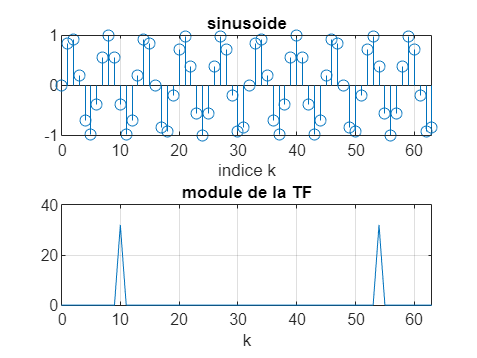

clear all;
close all;

% Domaine temporel
N=64;
fe=128;
Te=1/fe;
k=0:N-1;
t=k*Te;
x=sin(2*pi*20*k*Te);

figure
subplot(211)
stem(k, x)
xlabel('indice k')
title('sinusoide')
grid on
subplot(212)
stem(t,x)
xlabel('temps t')
grid on
title('sinusoide')


X=fft(x); % fft pour faire la TFTD, X est un vecteur de nombres complexes
magX=abs(X);
plot(k,magX), title('module de la TF'), xlabel('k'), grid

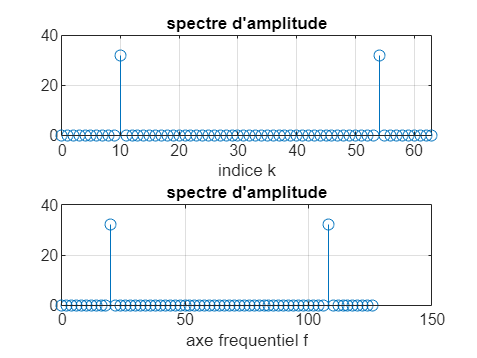

% 64 points
% intervalle de 1

% Domaine fréquentiel
fe=1/Te;
f=k*fe/N;

X=fft(x);
magX=abs(X);

figure
subplot(211)
stem(k,magX)
xlabel('indice k')
title('spectre d''amplitude')
grid on
subplot(212)
stem(f, magX)
xlabel('axe frequentiel f')
title('spectre d''amplitude')
grid on

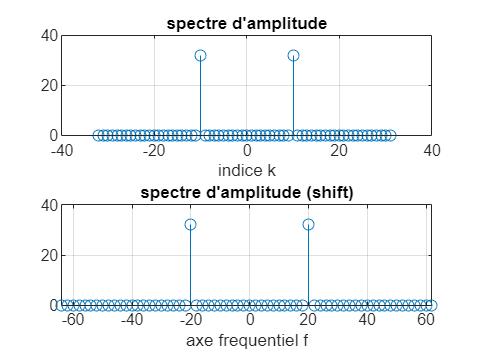


% fftshift (elle ne fait pas de TF, elle permet seulement de couper le
% vecteur de X en 2, et mettre la 2e partie en premier pour centrer le tout
% sur l'origine par exemple
% Distance entre chaque point : fe/Nf avec Nf = 2N
ks=-N/2:N/2-1;
fs=ks*fe/N;

Xs=fftshift(X);
magXs=abs(Xs);

figure
subplot(211)
stem(ks,magXs)
xlabel('indice k')
title('spectre d''amplitude')
grid on
subplot(212)
stem(fs,magXs)
xlabel('axe frequentiel f')
title('spectre d''amplitude (shift)')
grid on

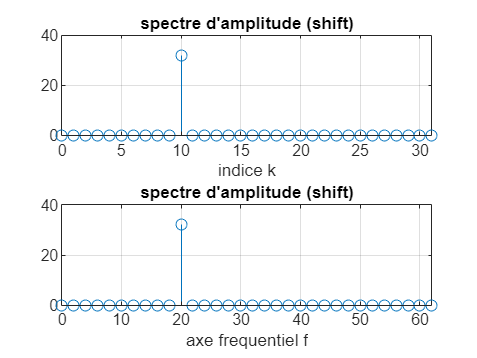


% Uniquement freq positive
figure
subplot(211)
stem(k(1:N/2), magX(1:N/2))
xlabel('indice k')
title('spectre d''amplitude (shift)')
grid on
subplot(212)
stem(f(1:N/2), magX(1:N/2))
xlabel('axe frequentiel f')
title('spectre d''amplitude (shift)')
grid on

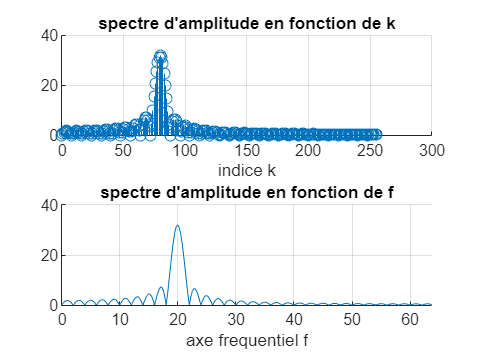


% Zero padding - méthode 1
Nz=448;
x1=[x(:)' zeros(1,Nz)];

Nf=length(x1);
k=0:Nf-1;
f=k*fe/Nf;

X1=fft(x1);
magX1=abs(X1);

figure
subplot(211)
hold on
stem(k(1:Nf/2), magX1(1:Nf/2))
xlabel('indice k')
title('spectre d''amplitude en fonction de k')
grid on
subplot(212)
hold on
plot(f(1:Nf/2), magX1(1:Nf/2))
xlabel('axe frequentiel f')
title('spectre d''amplitude en fonction de f')
grid on

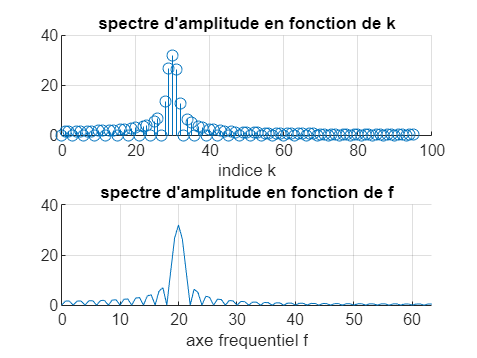


% Zero padding - méthode 2
X=fft(x,3*N);
Nf=length(X);
k=0:Nf-1;

f=k*fe/Nf;
magX=abs(X);

figure
subplot(211)
hold on
stem(k(1:Nf/2), magX(1:Nf/2))
xlabel('indice k')
title('spectre d''amplitude en fonction de k')
grid on
subplot(212)
hold on
plot(f(1:Nf/2), magX(1:Nf/2))
xlabel('axe frequentiel f')
title('spectre d''amplitude en fonction de f')
grid on

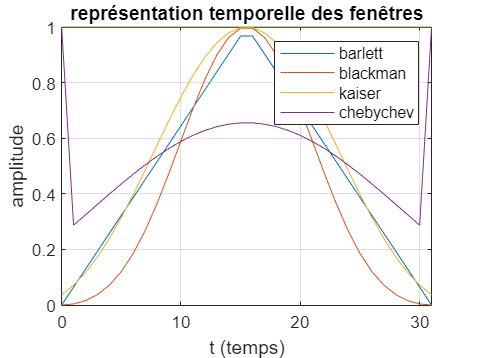



N=32;
k=0:N-1;
Te=1;
fe=1/Te;
t=k*Te;
f1=bartlett(N);
f2=blackman(N);
f3=kaiser(N, 5);
f4=chebwin(N, 20);
frect=rectwin(N);

figure
plot(t, [f1,f2,f3,f4,frect])
grid on
xlabel('t (temps)')
ylabel('amplitude')
title('représentation temporelle des fenêtres')
legend('barlett','blackman','kaiser','chebychev')